net =   dlnetwork with properties:

         Layers: [237×1 nnet.cnn.layer.Layer]
    Connections: [337×2 table]
     Learnables: [149×3 table]
          State: [0×3 table]
     InputNames: {'images'}
    OutputNames: {'output0Output'}
    Initialized: 1

  View summary with summary.


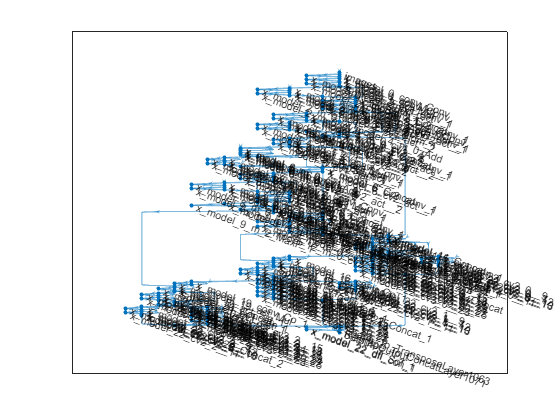

modelfile = "C:\Users\msi\Documents\ELTE\ImageandSignal\Assignment3\LicensePlateDetection\LicensePlate5\weights\best.onnx";
net = importNetworkFromONNX(modelfile)

imagePath = 'P9170012.jpg'; % Replace with your image path
inputImage = imread(imagePath);
resizedImage = imresize(inputImage, [640, 640]);

% Normalize the image (if required by your model)
inputImageNormalized = double(resizedImage) / 255; % Normalize to [0, 1]

inputImageBatch = permute(inputImageNormalized, [1, 2, 3, 4]); % Convert to [Batch, Height, Width, Channels]

% Predict bounding boxes and other outputs
outputs = detect(net, inputImageBatch);

Unrecognized function or variable 'detect'.

% Example post-processing (this depends on your model's output structure)
boundingBoxes = outputs(:, 1:4); % Assuming first 4 values are bounding box coordinates
confidenceScores = outputs(:, 5); % Assuming 5th value is confidence score
classScores = outputs(:, 6:end); % Assuming remaining are class probabilities

boundingBoxes

boundingBoxes = 1×4 single row vector
    5.4930    3.7776  132.2432  125.3843


confidenceScores

confidenceScores = single
5.5719e-07

classScores

classScores = 1×41995 single row vector
   14.6948    4.5669  120.1086  118.9518    0.0000   28.2892    7.6093   78.2302   95.0733    0.0000   32.1393   11.1720   54.9569   71.5798    0.0000   31.9813   12.1372   66.9604   72.2047    0.0000   38.7144   10.1876   80.5667   76.9473    0.0000   52.4565    8.7195   82.5508   88.4290    0.0000   63.1135    8.8492   82.2595   90.6284    0.0000   70.2133    9.4796   81.6115   88.6660    0.0000   76.2799    9.8699   84.9944   88.0927    0.0000   81.9606    9.9512   94.2062   90.8002    0.0000
